# Comparing edge-based and marker-based tracking approaches for End Mill tool vibrations

vid = VideoReader("video1.mp4","CurrentTime",12);

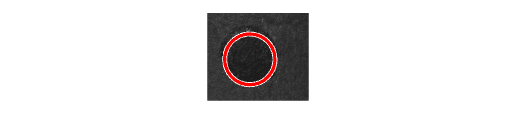

frame = readFrame(vid);
frame = rgb2gray(frame);
frame = imcrop(frame,[1 200 700 600]);
fedge = edge(frame,"canny",[],80);
%imshow(fedge);
[c,r] = imfindcircles(fedge,[100,300],"Sensitivity",0.95);
imshow(frame);
viscircles(c,r);

res = 5e-6; % Resolution in mm/pixel
marker_disp = [];
edge_disp = [];
time = [];
while vid.CurrentTime < 40
    frame = readFrame(vid);
%   frame = frame(460:540,1040:1155,1);
%   frameEdge = edge(frame,"canny",[0.2,0.7],8);
%   [center,radius] = imfindcircles(frameEdge,[230,270]);
%   x = center(1)*res - res/2;

    frame = rgb2gray(frame);
    marker_frame = imcrop(frame,[1 200 700 600]);
    marker_fedge = edge(marker_frame,"canny",[],80);
    edge_frame = imcrop(frame,[1400 400 500 200]);
    edge_fedge = edge(edge_frame,"canny",[0.2 0.7],16);
    %imshowpair(edge_frame,edge_fedge,'montage');
    edge_x = find(edge_fedge);
    edge_x=(edge_x/202)+1;
    edge_x = mean(edge_x);
    edge_x = edge_x*res - res/2;
    marker_x = find(marker_fedge);
    marker_x=(marker_x/702)+1;
    marker_x = mean(marker_x);
    marker_x = marker_x*res - res/2;
    %[center,radius] = imfindcircles(marker_fedge,[100,300],"Sensitivity",0.95);
    %disp = [disp,center(2)];
    marker_disp = [marker_disp,marker_x];
    edge_disp = [edge_disp,edge_x];
    time = [time,vid.CurrentTime-12];
    %if (size(center) ~= [1,2])
    %    imshow(frameEdge);
    %    viscircles(center,radius,'EdgeColor','g');
    %    disp(vid.CurrentTime);
    %end
    %pause(0.1);
end

offset = mean(marker_disp);
marker_disp = marker_disp - offset;
offset = mean(edge_disp);
edge_disp = edge_disp - offset;

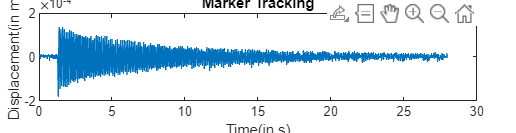

plot(time,marker_disp);
title('Marker Tracking');
xlabel('Time(in s)');
ylabel('Displacement(in m)');

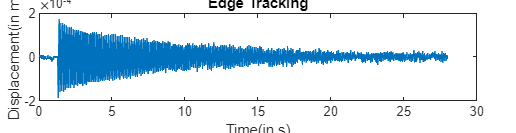

plot(time,edge_disp);
title('Edge Tracking');
xlabel('Time(in s)');
ylabel('Displacement(in m)');

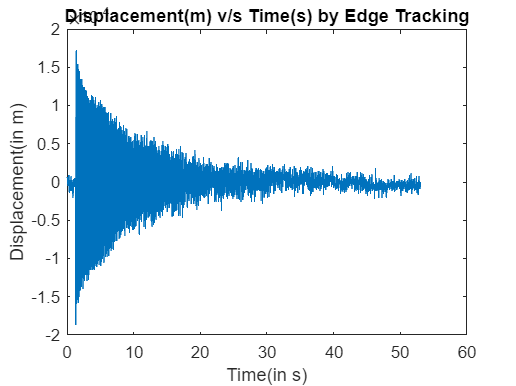

res = 5e-6;
disp = [];
time = [];
while vid.CurrentTime < 65
    frame = readFrame(vid);
    %frame = frame(460:540,1040:1155,1);
    % frameEdge = edge(frame,"canny",[0.2,0.7],8);
    % [center,radius] = imfindcircles(frameEdge,[230,270]);
    % x = center(1)*res - res/2;

    frame = rgb2gray(frame);
    frame = imcrop(frame,[1400 400 500 200]);
    fedge = edge(frame,"canny",[0.2 0.7],16);
    %imshowpair(frame,fedge,'montage');
    x = find(fedge);
    x=(x/202)+1;
    x = mean(x);
    x = x*res - res/2;
    %[center,radius] = imfindcircles(fedge,[150,250]);
    %disp = [disp,center(2)];
    disp = [disp,x];
    time = [time,vid.CurrentTime-12];
    %if (size(center) ~= [1,2])
    %    imshow(frameEdge);
    %    viscircles(center,radius,'EdgeColor','g');
    %    disp(vid.CurrentTime);
    %end
    %pause(0.5);
end
offset = mean(disp);
disp = disp - offset;
plot(time,disp);
title('Displacement(m) v/s Time(s) by Edge Tracking');
xlabel('Time(in s)');
ylabel('Displacement(in m)');